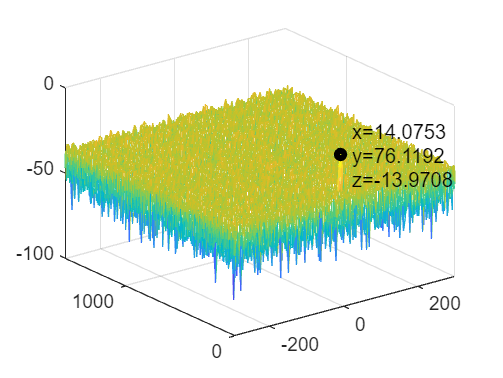

% OFDM setting
fc = 24e9;       % Carrier frequency (Hz)
B = 100e6;       % Bandwidth (Hz)
fs = B;          % Set the sample rate equal to the bandwidth
Nsc = 1024;      % Number of subcarriers
df = B/Nsc;      % Separation between subcarriers
Tsym = 1/df;     % OFDM symbol duration
Ncp = 16;        % OFDM cyclic prefix length
Tcp = Ncp/fs;    % CP duration affects the sensing range
Tofdm = Tsym + Tcp; % OFDM symbol duration with CP
Nofdm = Nsc + Ncp;  % Number of samples in one OFDM symbol
Mofdm = 128;        % Number of transmitted OFDM symbols

% 信道参数
PowerdB = [0 -8 -17 -21 -25]; % 多径功率谱 (dB)
Delay = [0 3 5 6 8];          % 多径延迟 (采样数)
L = length(PowerdB);          % 信道路径数
SNR = 20;                     % 信噪比
% 将功率谱转换为线性值
PowerLinear = 10.^(PowerdB / 10);
% 创建信道冲激响应 (h)
h = zeros(max(Delay) + 1, 1); % 分配冲激响应长度
for p = 1:L
    h(Delay(p) + 1) = PowerLinear(p); % 按延迟位置分配功率增益
end

% Modulation order
bps = 4;         % Bits per QAM symbol (and OFDM data subcarrier)
K = 2^bps;       % Modulation order
dataTx = randi([0,1], [Nsc*bps Mofdm]); % binary data
qamTx = qammod(dataTx, K, 'InputType', 'bit', 'UnitAveragePower', true);
ofdmTx = ofdmmod(qamTx, Nsc, Ncp); % generate OFDM transmitted data
%经行信道衰减和随机噪声
ofdmTrans = conv(ofdmTx, h, 'same');
ofdmRx = awgn(ofdmTrans,SNR);
%接收机转化
xofdm = reshape(ofdmTx, Nofdm, Mofdm); % reshape, each column is one OFDM symbol
% xofdm: the input OFDM symbol of the size (OFDM number)x(Subcarrier No)
% fc: carrier frequency
% fs: sampling rate
% Tofdm: ofdm duration
% yofdmr: the received signal after reflecting from the target
yofdmr = receiveSignal_singleTarget(xofdm,fs,fc,Tofdm);
% Demodulate the OFDM signal and remove the data sample to get the matrix F
yofdmr1 = reshape(yofdmr, Nofdm * Mofdm, 1);
Yofdm = ofdmdemod(yofdmr1, Nsc, Ncp);
qamRx = ofdmdemod(ofdmRx, Nsc, Ncp);
Zofdmr = Yofdm ./ qamRx;
rdr = phased.RangeDopplerResponse('RangeMethod', 'FFT', ...
    'SampleRate', fs, 'SweepSlope', -B/Tofdm, ...
    'RangeWindow', 'Hamming', 'DopplerWindow', 'Hamming', ...
    'DopplerOutput', 'Speed', 'OperatingFrequency', fc, ...
    'PRFSource', 'Property', 'PRF', 1/Tofdm, ...
    'ReferenceRangeCentered', false);
[resp, rngGrid, dopGrid] = step(rdr, Zofdmr);
rdResponse = abs(resp);
% figure;
% imagesc(dopGrid, rngGrid, mag2db(rdResponse));
% xlim([0,50]);
% ylim([0,200]);
[XF,YF] = meshgrid(dopGrid,rngGrid);
figure();
mesh(XF,YF,mag2db(rdResponse))
% 找出 rdResponse 的最大值及其对应的下标
rdResponsemax = max(max(rdResponse));   % 找出最大值
[id_ymax, id_xmax] = find(rdResponse == rdResponsemax);  % 找出最大值对应的索引

% 根据索引找到对应的 doppler 和 range 坐标
xmax = dopGrid(id_xmax);  % 最大值的 x 坐标
ymax = rngGrid(id_ymax);  % 最大值的 y 坐标
hold on;
plot3(xmax, ymax, mag2db(rdResponsemax), 'k.', 'markersize', 20);  % 标记最大值点
text(xmax, ymax, mag2db(rdResponsemax), ...
    ['  x=', num2str(xmax), char(10), ...
     '  y=', num2str(ymax), char(10), ...
     '  z=', num2str(mag2db(rdResponsemax))], ...
    'Color', 'k');  % 标注坐标

F2Zofdmr = fft2(Zofdmr);
F2AMP = abs(F2Zofdmr);
n = 1:1024

n =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


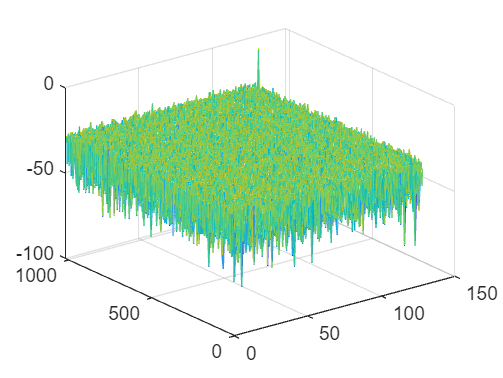

y = 1:128;
[X,Y]=meshgrid(y,n);
figure();
mesh(X,Y,mag2db(F2AMP));

%信噪比小于20左右感知机就报废了